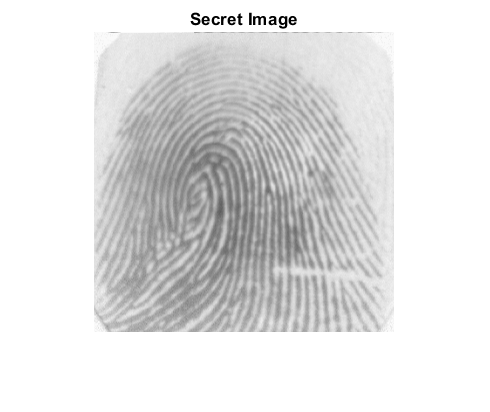

clc;
clear;
close all;
%Read Input Binary Secret Image
inImg = imread('102_3.tif');
figure;
imshow(inImg);title('Secret Image');

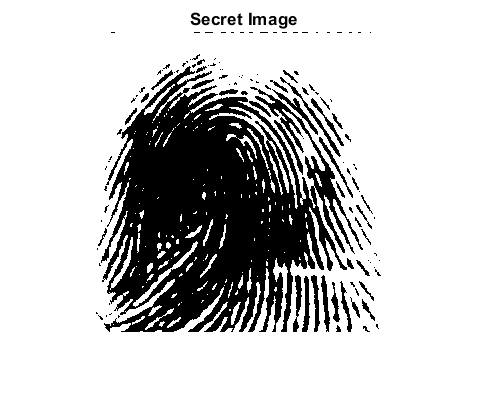


inImg = imbinarize(inImg);

figure;
imshow(inImg);title('Secret Image');


%Visual Cryptography
[share1, share2, share12] = VisCrypt(inImg);

White Pixel Processing...
Black Pixel Processing...
Share Generation Completed.



%Outputs
figure;
subplot(321)
imshow(share1);title('Share 1 - first time');
subplot(323)
imshow(share2);title('Share 2 -first time');
% figure;imshow(share12);title('Overlapping Share 1 & 2');

s =size(inImg);
shareop = zeros(size(inImg));
for i = 1:s(1)
    for j = 1:s(2)
        a = share12(i,(2*j-1):(2*j));
        shareop(i,j) = max(a);
    end
end
%  imwrite(share1,'Share1.tif');
%  imwrite(share2,'Share2.tif');
% imwrite(share12,'Overlapped.bmp');

subplot(325)
imshow(shareop);title('Share op 1');

%Visual Cryptography second time
[share1_2, share2_2, share12_2] = VisCrypt(inImg);

White Pixel Processing...
Black Pixel Processing...
Share Generation Completed.


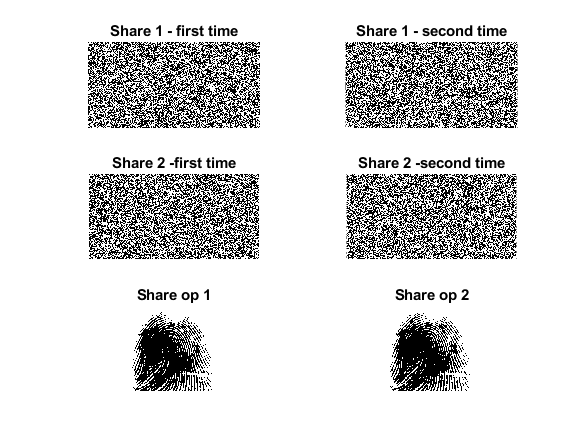


%Outputs
subplot(322)
imshow(share1_2);title('Share 1 - second time');
subplot(324)
imshow(share2_2);title('Share 2 -second time');
% figure;imshow(share12);title('Overlapping Share 1 & 2');

s =size(inImg);
shareop_2 = zeros(size(inImg));
for i = 1:s(1)
    for j = 1:s(2)
        a = share12_2(i,(2*j-1):(2*j));
        shareop_2(i,j) = max(a);
    end
end
%  imwrite(share1,'Share1.tif');
%  imwrite(share2,'Share2.tif');
% imwrite(share12,'Overlapped.bmp');

subplot(326)
imshow(shareop_2);title('Share op 2');


if shareop==inImg & shareop_2 ==inImg
    disp('Correct decoding')
end

Correct decoding



disp("To show probalilistic nature of shares generation")

To show probalilistic nature of shares generation



if share1 == share1_2
    disp("Share 1 generated first and second time are equal")
else
    disp("Share 1 generated first and second time are not equal")
end

Share 1 generated first and second time are not equal


if share2 == share2_2
    disp("Share 2 generated first and second time are  equal")
else
    disp("Share 2 generated first and second time are not equal")
end

Share 2 generated first and second time are not equal



disp("To show we need the correct shares for decoding,")

To show we need the correct shares for decoding,


disp("we will now show output if share 1 and share2_2 are used")

we will now show output if share 1 and share2_2 are used


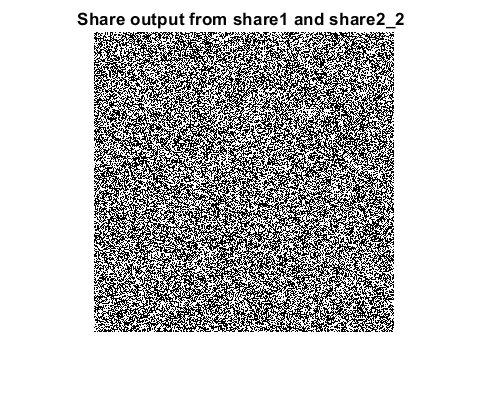


share12_w=bitor(share1, share2_2);
share12_w = ~share12_w;
shareop_w = zeros(size(inImg));
for i = 1:s(1)
    for j = 1:s(2)
        a = share12_w(i,(2*j-1):(2*j));
        shareop_w(i,j) = max(a);
    end
end
figure;
imshow(shareop_w);title('Share output from share1 and share2\_2 ');

if shareop_w==inImg
    disp('Correct decoding')
else
    disp('InCorrect decoding')
end

InCorrect decoding


function [share1, share2, share12] = VisCrypt(inImg)
s = size(inImg);
share1 = zeros(s(1), (2 * s(2)));
share2 = zeros(s(1), (2 * s(2)));
%%White Pixel Processing
%White Pixel share combinations
disp('White Pixel Processing...');
s1a=[1 0];
s1b=[1 0];
[x y] = find(inImg == 1);
len = length(x);
for i=1:len
    a=x(i);b=y(i);
    pixShare=generateShare(s1a,s1b);
    share1((a),(2*b-1):(2*b))=pixShare(1,1:2);
    share2((a),(2*b-1):(2*b))=pixShare(2,1:2);
end
%Black Pixel Processing
%Black Pixel share combinations
disp('Black Pixel Processing...');
s0a=[1 0];
s0b=[0 1];
[x y] = find(inImg == 0);
len = length(x);
for i=1:len
    a=x(i);b=y(i);
    pixShare=generateShare(s0a,s0b);
    share1((a),(2*b-1):(2*b))=pixShare(1,1:2);
    share2((a),(2*b-1):(2*b))=pixShare(2,1:2);
end
share12=bitor(share1, share2);
share12 = ~share12;
disp('Share Generation Completed.');
end

function out = generateShare(a,b)
a1 = a(1);
a2 = a(2);
b1 = b(1);
b2 = b(2);
in = [a
    b];
out = zeros(size(in));
randNumber = floor(1.9*rand(1));
if (randNumber == 0)
    out = in;
elseif (randNumber == 1)
    a(1) = a2;
    a(2) = a1;
    b(1) = b2;
    b(2) = b1;
    out = [a
        b];
end

end
